# Generate Alternative Trajectories for Reference Path

Generate alternative trajectories for a reference path using Frenet coordinates. Specify different initial and terminal states for your trajectories. Tune your states based on the generated trajectories.

Generate a reference path from a set of waypoints. Create a `trajectoryGeneratorFrenet` object from the reference path.

waypoints = [19.3392323770315	-52.2882461200238;...
21.0600000000000	-62.9300000000000;...
25.6000000000000	-66.8000000000000;...
30.4000000000000	-69.4000000000000;...
35.7000000000000	-69.2000000000000;...
41.8000000000000	-68.3000000000000;...
48.6000000000000	-64.5000000000000;...
56.1000000000000	-64.4000000000000;...
61.3000000000000	-66.1000000000000;...
65	-68;...
70.9000000000000	-72.6000000000000;...
76.4000000000000	-75.8000000000000;...
80.1000000000000	-75.8000000000000;...
86.4000000000000	-72.8000000000000;...
88.6000000000000	-67.7000000000000;...
88.9000000000000	-62.3000000000000;...
87.6000000000000	-52;...
87.5000000000000	-40.4000000000000;...
85.5000000000000	-29.8000000000000;...
82.4000000000000	-25.8000000000000;...
78.4000000000000	-22.3000000000000;...
72.7000000000000	-20.7000000000000;...
67.6000000000000	-21;...
65	-22.1000000000000;...
60.8000000000000	-24.5000000000000;...
57.3000000000000	-32.3000000000000;...
54.1000000000000	-39.1000000000000;...
50.5000000000000	-42.9000000000000;...
46.7000000000000	-42.8000000000000;...
41.9000000000000	-42.1000000000000;...
38.5000000000000	-39.8000000000000;...
32.5000000000000	-36.3000000000000;...
27.0000000000000	-37.5000000000000;...
22.4000000000000	-41.2000000000000;...
20.5000000000000	-46.0000000000000;...
19.2000000000000	-53.5000000000000;...
19.1800000000000	-53.5700000000000];
refPath = referencePathFrenet(waypoints);
connector = trajectoryGeneratorFrenet(refPath);

Generate a five-second trajectory between the path origin and a point 30 m down the path as Frenet states.

initState = [0 0 0 0 0 0];  % [S ds ddS L dL ddL]
termState = [20 0 0 0 0 0]; % [S ds ddS L dL ddL]
[~,trajGlobal] = connect(connector,initState,termState,5);

Display the trajectory in global coordinates.

show(refPath);
hold on
axis equal
plot(trajGlobal.Trajectory(:,1),trajGlobal.Trajectory(:,2),'b')
legend(["Waypoints","Reference Path","Trajectory to 30m"])

ReferencePathLine = findobj(gcf, "DisplayName", "Reference Path")

ReferencePathLine =   Line (Reference Path) - 属性:

              Color: [0.8510 0.3255 0.0980]
          LineStyle: '-.'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [19.3392 19.3356 19.3320 19.3284 19.3248 19.3213 19.3177 19.3141 19.3106 19.3070 19.3035 19.3000 19.2964 19.2930 19.2895 19.2860 19.2826 19.2792 19.2758 19.2725 19.2691 19.2658 19.2626 19.2593 19.2561 19.2530 … ] (1×4462 double)
              YData: [-52.2882 -52.3381 -52.3880 -52.4379 -52.4877 -52.5376 -52.5875 -52.6373 -52.6872 -52.7371 -52.7870 -52.8368 -52.8867 -52.9366 -52.9865 -53.0364 -53.0862 -53.1361 -53.1860 -53.2359 -53.2858 -53.3357 -53.3856 … ] (1×4462 double)

  显示 

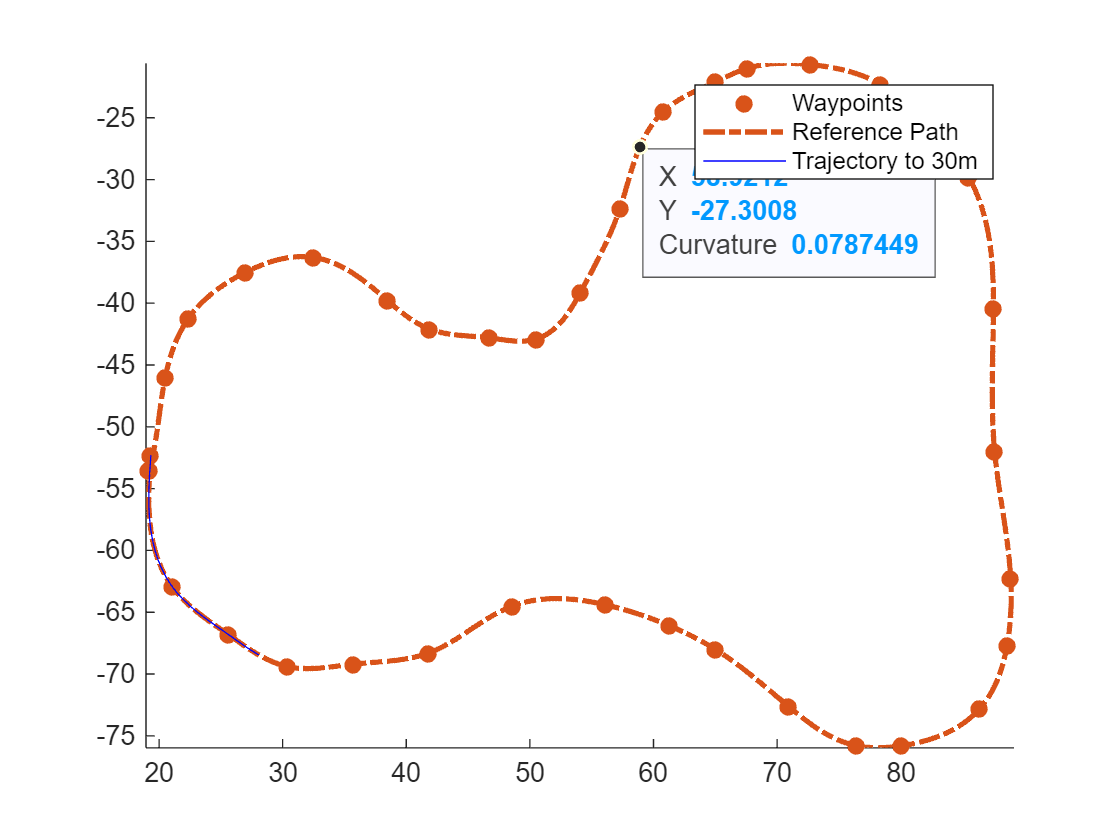

datatip(ReferencePathLine,58.92,-27.3);

Create a matrix of terminal states with lateral deviations between –3 m and 3 m. Generate trajectories that cover the same arc length in 10 seconds, but deviate laterally from the reference path. Display the new alternative paths.

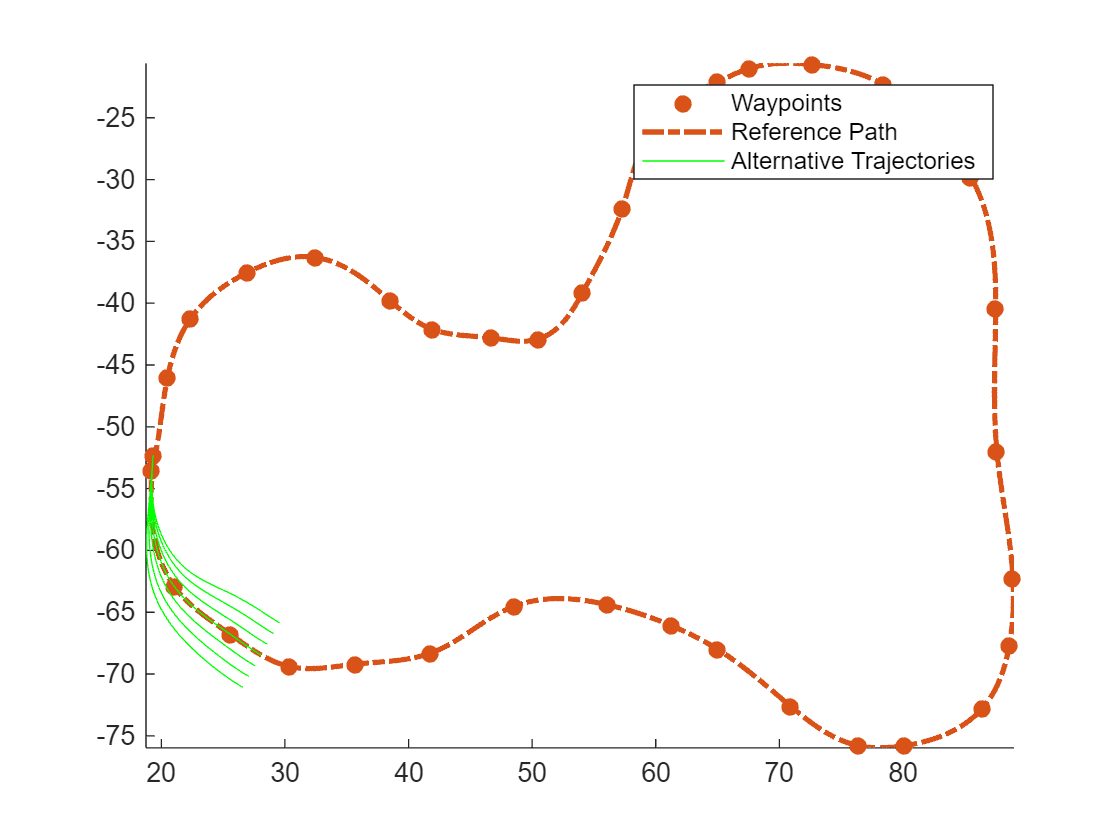

termStateDeviated = termState + ([-3:3]' * [0 0 0 1 0 0]);
[~,trajGlobal] = connect(connector,initState,termStateDeviated,10);

clf
show(refPath);
hold on
axis equal
for i = 1:length(trajGlobal)
    plot(trajGlobal(i).Trajectory(:,1),trajGlobal(i).Trajectory(:,2),'g')
end
legend(["Waypoints","Reference Path","Alternative Trajectories"])
hold off

Specify a new terminal state to generate a new trajectory. This trajectory is not desirable because it requires reverse motion to achieve a longitudinal velocity of 10 m/s.

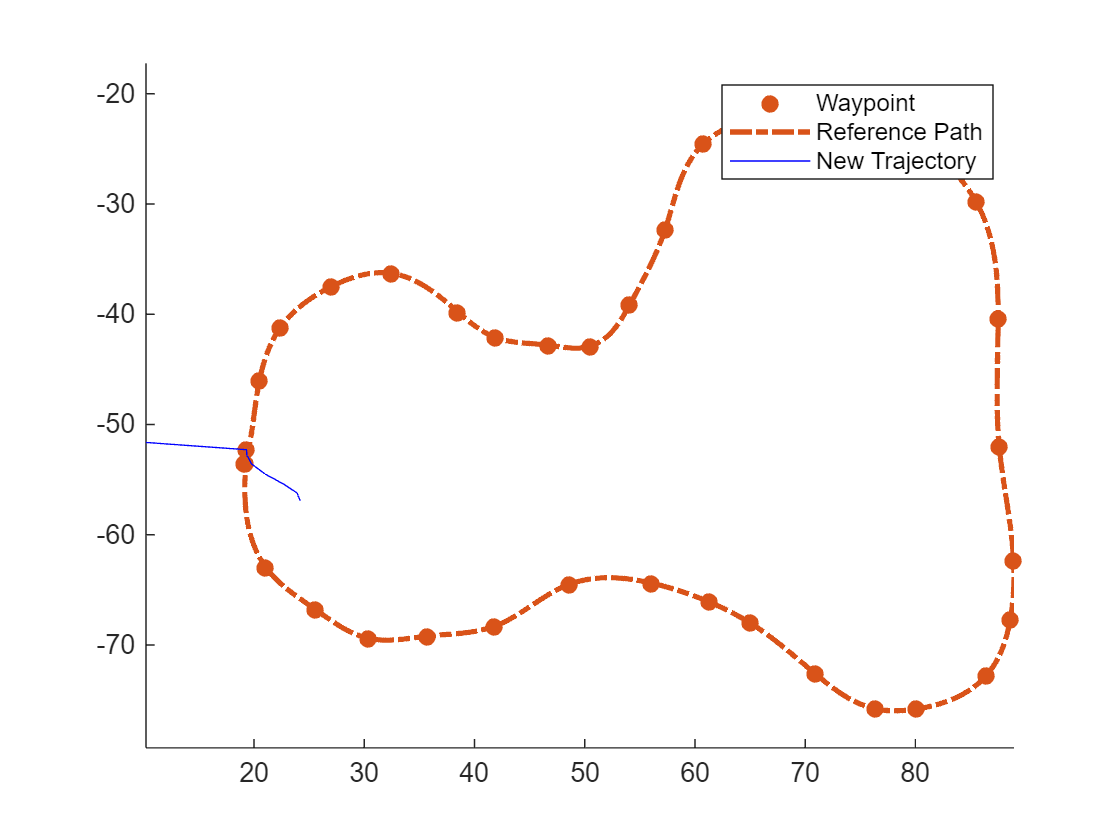

newTermState = [5 10 0 5 0 0];
[~,newTrajGlobal] = connect(connector,initState,newTermState,3);

clf
show(refPath);
hold on
axis equal
plot(newTrajGlobal.Trajectory(:,1),newTrajGlobal.Trajectory(:,2),'b');
legend(["Waypoint","Reference Path","New Trajectory"])
hold off

Relax the restriction on the longitudinal state by specifying an arc length of `NaN`. Generate and display the trajectory again. The new position shows a good alternative trajectory that deviates off the reference path.

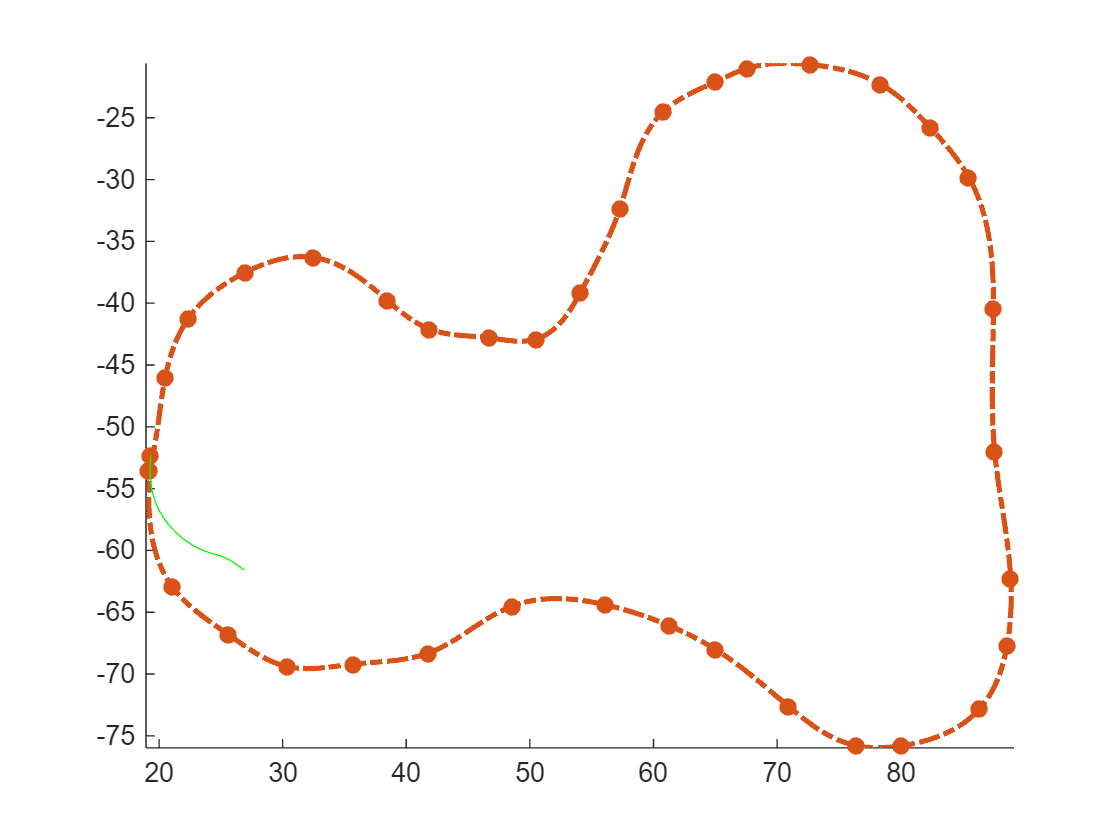

relaxedTermState = [NaN 10 0 5 0 0];
[~,trajGlobalRelaxed] = connect(connector,initState,relaxedTermState,3);

clf
show(refPath);
hold on
axis equal
plot(trajGlobalRelaxed.Trajectory(:,1),trajGlobalRelaxed.Trajectory(:,2),'g');
hold off

*Copyright 2020 The MathWorks, Inc.*